a=1+mod(964,3);

Q1A

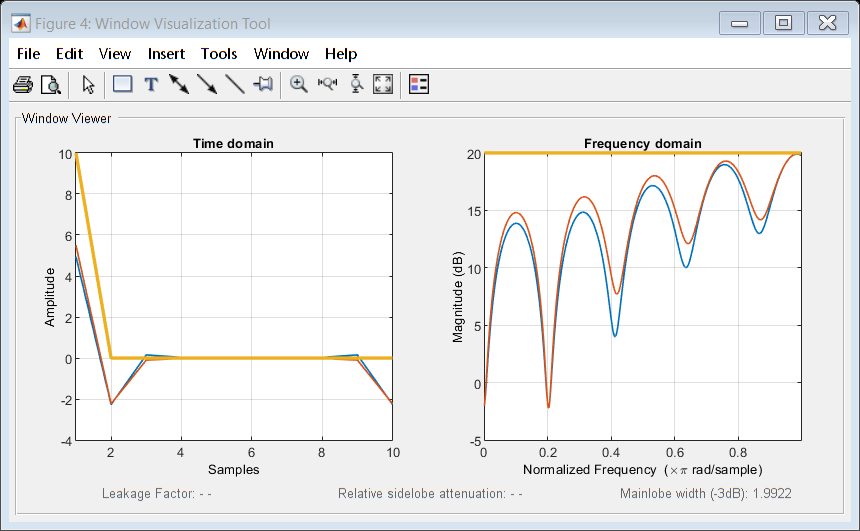

L=10;
fs=44100;
Ham=hamming(L);
Hann=hanning(L);
rect=rectwin(L);
y1=fft(Ham);
z1=fftshift(y1);
y2=fft(Hann);
z2=fftshift(y2);
y3=fft(rect);
z3=fftshift(y3);
fvec1=(0:length(y1)-1)*fs/length(y1);
fvec2=(0:length(y2)-1)*fs/length(y2);
fvec3=(0:length(y3)-1)*fs/length(y3);
amplitude_spectrum1=abs(z1)/fs;
amplitude_spectrum2=abs(z2)/fs;
amplitude_spectrum3=abs(z3)/fs;
% plot((fvec1)',mag2db(abs(z1)))
% % plot((fvec1)',z1)
% title("Hamming window")
% ylabel("Amplitude(dB)")
% xlabel("Frequency(Hz)")
% % plot((fvec2)',z2)
% plot((fvec2)',mag2db(abs(z2)))
% title("Hanning window")
% ylabel("Amplitude(dB)")
% xlabel("Frequency(Hz)")
% % plot((fvec3)',z3)
% plot((fvec3)',db(z3))
% title("Rectangular window")
% ylabel("Amplitude")
% xlabel("Frequency(Hz)")

wvtool(y1,y2,y3)

% legend("Hamming window","Hanning window","Rectangular window")

Q1B

Nfft = 1024;
N =[100 200 300];
fs = 500;
for i=1:1:length(N)
blackwin = blackman(N(i));
spectrum = abs(fft(blackwin, Nfft));
spectrum = spectrum/N(i);
f = (0:Nfft-1)*(fs/Nfft);
subplot(length(N), 1, i);
stem(f,spectrum);
xlabel('Frequency (Hz)');
ylabel('Normalized Magnitude');
title(['Blackman Window Spectrum for N =',num2str(N(i))]);
end
figure;

Q2

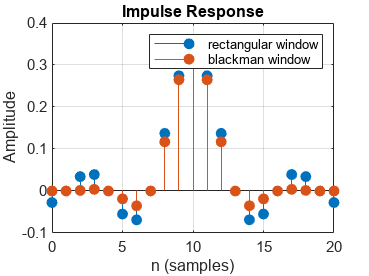

clear
a=2;
wc=pi/(a+1);
L=21;
rectangularwin=fir1(L-1,wc/(pi),'low',rectwin(L));
[br,ar]=fir1(L-1,wc/(pi),'low',rectwin(L));
blackmanwin=fir1(L-1,wc/(pi),'low',blackman(L));
[bb,ab]=fir1(L-1,wc/(pi),'low',blackman(L));
figure;impz(rectangularwin);
hold on
impz(blackmanwin);
grid on
hold off
legend("rectangular window","blackman window")

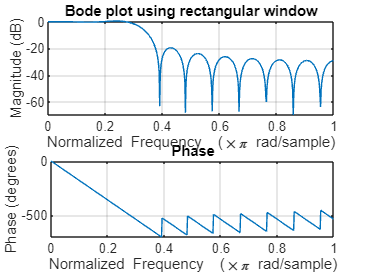

freqz(br,ar)
%figure;bode(br,ar)
title("Bode plot using rectangular window")
grid on

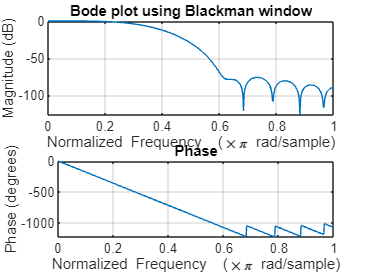

%figure;bode(bb,ab)
freqz(bb,ab)
title("Bode plot using Blackman window")
grid on

Q3

figure;
[s,fs]=audioread("instru2.wav");
y=fft(s);
m=abs(y);
y(m<1e-5)=0;
fvec=(0:length(y)-1)*fs/length(y);
[~,idx]=max(m);
fun_freq=fvec(idx)
overlap=900;
N=2000;
[S,F,T]=spectrogram(s,hamming(N),10,1000,fs,"xaxis");
imagesc(T,F,10*log10(abs(S)));
axis xy;
colorbar;
colormap('jet')
xlabel('Time(s)')
ylabel('Frequency(in Hz)')
title('Spectrogram of instru2.wav')

wc=2*pi*fun_freq;
start=2368/(fs/2);
stop=2370/(fs/2);
[bfil,afil]=fir1(N,[start stop],"bandpass");%hamming window by default
filteredinstru=filter(bfil,afil,s);
audiowrite("Filteredinstru2.wav",filteredinstru,fs)
[s1,fs1]=audioread("Filteredinstru2.wav");
y1=fft(s1);
m1=abs(y1);
y1(m1<1e-5)=0;
fvec1=(0:length(y1)-1)*fs1/length(y1);
[~,idx1]=max(m1);
fun_freq1=fvec(idx1)
[S1,F1,T1]=spectrogram(s1,hamming(N),10,1000,fs1,"xaxis");
imagesc(T1,F1,10*log10(abs(S1)));
axis xy;
colorbar;
colormap('jet')
xlabel('Time(s)')
ylabel('Frequency(in Hz)')
title('Spectrogram of Filteredinstru2.wav')